num1=[1 2 9];
den1=[1 2 4 7 2];
sys1=tf(num1,den1)


sys1 =
 



num2=[-5];
den2=[1 -2 5];
k=7;
sys2=zpk(num2,den2,k)

num=7*[2 5];
den=conv(conv([1 0 0],[3 2]),conv([2 7 8],[4 5]));
sys1=tf(num,den)

num1=2;     den1=[1 3 2]; sys1=tf(num1,den1);
num2=[1 6]; den2=[1 2 5]; sys2=tf(num2,den2);
sys1=series(sys1,sys2)

num1=[2 9]; den1=[4 7 2]; sys1=tf(num1,den1);
num2=[1 6]; den2=[1 7 1]; sys2=tf(num2,den2);
sys1=parallel(sys1,sys2)

num1=[2 9]; den1=[2 6 5]; sys1=tf(num1,den1);
sys2=1;
PositiveFeedback=feedback(sys1,sys2,1)
NegativeFeedback=feedback(sys1,sys2,-1)

wn=1;
n1=0.1; sys1=tf(wn^2,[1 2*n1*wn wn^2]);
n2=0.3; sys2=tf(wn^2,[1 2*n2*wn wn^2]);
n3=0.7; sys3=tf(wn^2,[1 2*n3*wn wn^2]);
n4=1;   sys4=tf(wn^2,[1 2*n4*wn wn^2]);
t=1:0.03:60;
y1=step(sys1,t);
y2=step(sys2,t);
y3=step(sys3,t);
y4=step(sys4,t);
plot(t,y1,t,y2,t,y3,t,y4);
hold on;grid on;
[y2m,k2m]=max(y2);
line(t(k2m),y2m,'marker','.','markeredgecolor','r','markersize',20);
y2str=['y2max = ',sprintf('%1.6g\',y2m)];

t2str=['t2max = ',sprintf('%1.4g\',t(k2m))];

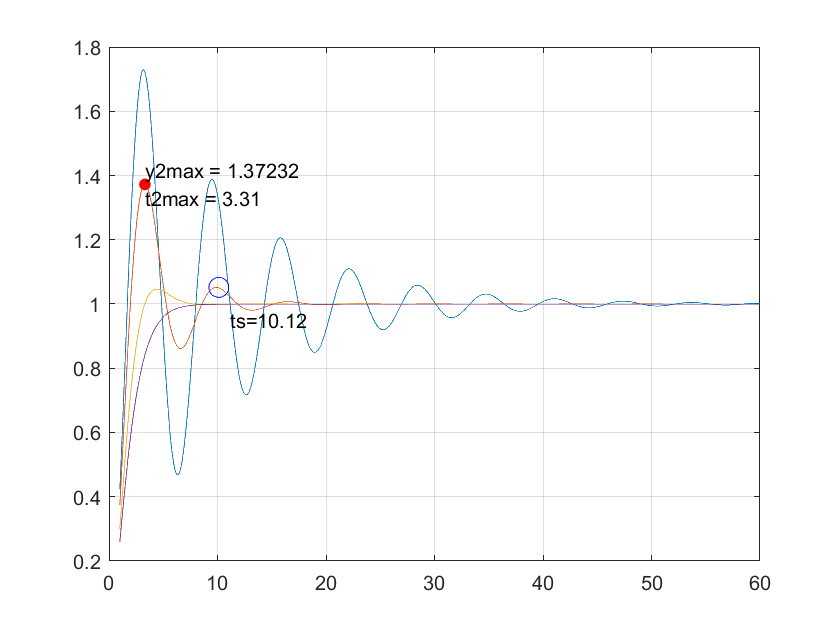

text(t(k2m),y2m,{y2str,t2str});
ttt=t(find(abs(y2-1)>0.05));
ts=max(ttt);
plot(ts,1.0516,'bo','MarkerSize',10);
hold off;
text(ts+1,0.95,['ts=',num2str(ts)]);

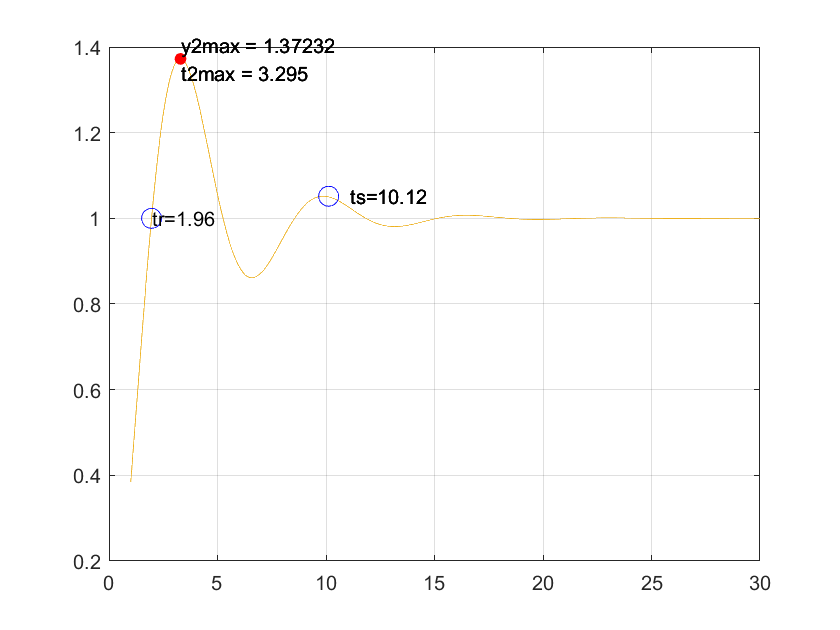

wn=1;
n2=0.3; sys2=tf(wn,[1 2*n2*wn wn^2]);
t=1:0.015:30;
y2=step(sys2,t);
plot(t,y2);
hold on;grid on;
[y2m,k2m]=max(y2);
line(t(k2m),y2m,'marker','.','markeredgecolor','r','markersize',20);
y2str=['y2max = ',sprintf('%1.6g',y2m)];
t2str=['t2max = ',sprintf('%1.4g',t(k2m))];
text(t(k2m),y2m,{y2str,t2str});
ttt=t(abs(y2-1)>0.05);
ts=max(ttt);
plot(ts,1.0516,'bo','MarkerSize',10);
text(ts+1,1.0516,['ts=',num2str(ts)]);
tttt=t(abs(y2-1)<0.001);
tr=min(tttt);
plot(tr,1,'bo','MarkerSize',10);
text(tr,1,['tr=',num2str(tr)]);

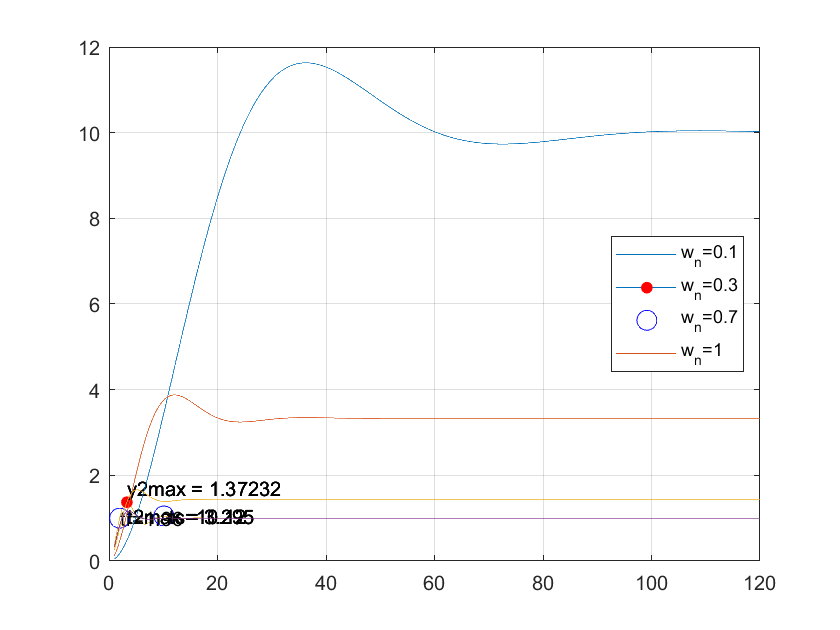

n=0.5;
wn1=0.1; sys1=tf(wn1^2,[1 2*n*wn1 wn1^2]);
wn2=0.3; sys2=tf(wn2^2,[1 2*n*wn2 wn2^2]);
wn3=0.7; sys3=tf(wn3^2,[1 2*n*wn3 wn3^2]);
wn4=1;   sys4=tf(wn4^2,[1 2*n*wn4 wn4^2]);
t=1:0.03:120;
y1=step(sys1,t);
y2=step(sys2,t);
y3=step(sys3,t);
y4=step(sys4,t);
plot(t,y1,t,y2,t,y3,t,y4);
hold on;grid on;
legend('w_n=0.1','w_n=0.3','w_n=0.7','w_n=1','Location','east');

n=0.5;
wn3=0.7; sys3=tf(wn3^2,[1 2*n*wn3 wn3^2]);
t=1:0.015:30;
y3=step(sys3,t);
plot(t,y3);
hold on;grid on;
[y3m,k3m]=max(y3);
line(t(k3m),y3m,'marker','.','markeredgecolor','r','markersize',20);
y3str=['y3max = ',sprintf('%1.6g',y3m)];
t3str=['t3max = ',sprintf('%1.4g',t(k3m))];
text(t(k3m),y3m,{y3str,t3str});
ttt=t(abs(y3-1)>0.05);
ts=max(ttt);
plot(ts,1.0516,'bo','MarkerSize',10);
text(ts,1.0516,['ts=',num2str(ts)]);
tttt=t(abs(y3-1)<0.002);
tr=min(tttt);
plot(tr,1,'bo','MarkerSize',10);
text(tr,1,['tr=',num2str(tr)]);